# Solution of Formative Task 3 - PCA

This script provides an example of solution for the formative task 3. It's not necessary to follow this solution if you could find your own way to complete this task.

## Question 1 - Loading Plot

Load the League of Legends Champions stats data from data.csv. Normalise the data and apply principal component analysis to calculate the principal component coefficients. Visualise the first and second principal components with a loading plot, explain the meaning of a loading plot, and describe what kind of information you can obtain from the loading plot.

### Answer 1

Load the data as a table. Have a look at the data and get some idea about the meanings of rows and columns. Here we can see each row represents a champion in League of Legends, and each column represents an ability. 

close all; clear; % initialise environment
T = readtable("data.csv", "ReadRowNames", 1, "PreserveVariableNames", 1) 

T = 141×12 table
                        Type         Attack range    Mp     Mp regen    Mp per level    Hp per level     Hp      Hp regen    Move speed    Attack damage    Armor    Spell block
                    _____________    ____________    ___    ________    ____________    ____________    _____    ________    __________    _____________    _____    ___________

    Aatrox          {'Fighters' }        175           0        0             0              90           580         3         345              60           38        32.1    
    Ahri        </

columnNames = string(T.Properties.VariableNames) % read table columns

columnNames = 1×12 string array
    "Type"    "Attack range"    "Mp"    "Mp regen"    "Mp per level"    "Hp per level"    "Hp"    "Hp regen"    "Move speed"    "Attack damage"    "Armor"    "Spell block"


Note the data contains text and numbers, so you need to extract the numerical data for the PCA analysis.

variables = columnNames(columnNames ~= "Type") % get variables (exclude type)

variables = 1×11 string array
    "Attack range"    "Mp"    "Mp regen"    "Mp per level"    "Hp per level"    "Hp"    "Hp regen"    "Move speed"    "Attack damage"    "Armor"    "Spell block"


X = T{:,variables} % get data

X =   175.0000         0         0         0   90.0000  580.0000    3.0000  345.0000   60.0000   38.0000   32.1000
  550.0000  418.0000    0.8000   25.0000   92.0000  526.0000    6.5000  330.0000   53.0000   20.9000   30.0000
  125.0000  200.0000         0         0   95.0000  575.0000    8.0000  345.0000   62.4000   23.0000   37.0000
  125.0000  350.0000    0.8000   40.0000  106.0000  573.4000    8.5000  330.0000   61.1000   44.0000   32.1000
  125.0000  287.0000    0.5000   40.0000   84.0000  613.1000    9.0000  335.0000   53.4000   33.0000   32.1000
  600.0000  495.0000    0.8000   25.0000   82.0000  480.0000    5.5000  325.0000   51.4000   21.2000   30.0000
  625.0000  418.0000    0.8000   25.0000   88.0000  524.0000    5.5000  335.0000   50.4000   19.2000   30.0000
  550.0000  348.0000    0.4000   42.0000   86.0000  530.0000    3.2500  330.0000   57.0000   28.0000   26.0000
  600.0000  280.0000    0.4000   32.0000   85.0000  539.0000    3.5000  325.0000   61.0000   26.0000   30.00

Note that the original data is biased, the values of some variables are significantly higher than the others, so it's necessary to perform normailsation before applying PCA to make all variables equally important. You can simply let the data subtract its mean and than divide by its standard deviation, in this way, you'll have a data with mean equals to zero and with standard deviation equals to one.

Xnorm = (X - mean(X)) ./ std(X,1); % normalisation
Xmean = mean(Xnorm)

Xmean = 	1.0e+-13 *

   -0.0007    0.0012    0.0139    0.0010   -0.0088   -0.0082    0.0021    0.0066    0.0189   -0.0032    0.1610


Xstd = std(Xnorm,1)

Xstd =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


 Specify the output of PCA to get all the information you need.

[coeff, scores, latent, ~, explained] = pca(Xnorm);

Draw the loading plot.

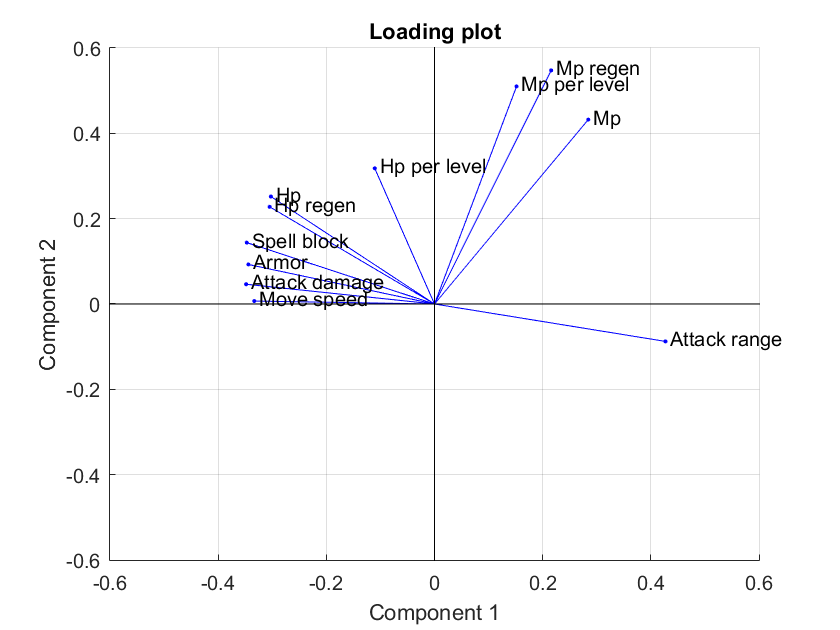

biplot(coeff(:,1:2), 'VarLabels', variables)
title('Loading plot')

The loading plot shows the contribution of each variables to the principal components. For example, we can see from the loading plot that the attach range is highly related to the first principal component, but not the second principal component. 

Besides, the angle between each variables in the loading plot is important. If the angle is close to zero, this implies that those variables are highly related to each other. We can see that from MoveSpeed, AttackDamage, Armor, SpellBlock, ...etc. If the angle is about 90 degree, this implies that those variables are not quite related. For instance, Mp and Hp. If the anlge is about 180 degree, this means those variables are inversely related to each other. For instance, AttackRange and AttackDamage.

## Question 2 - Bar Chart

Alternatively, use a bar chart to illustrate the principal component coefficients, and compare it with the loading plot: what's the pros and cons of a loading plot and a bar chart?

### Answer 2

In order to display the bar chart correctly, it's necessary to convert the variables into categorical and reorder them. 

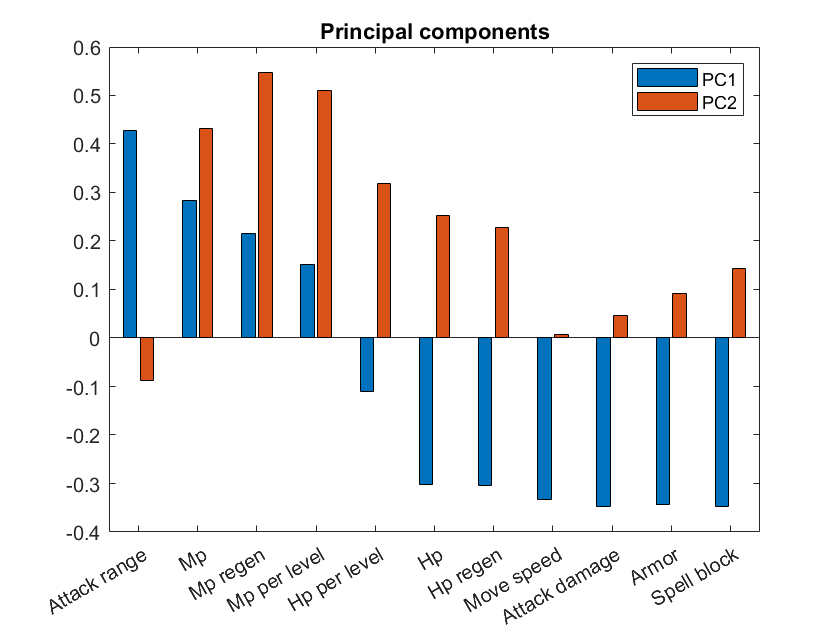

cats = categorical(variables); % convert data structure for bar chart
cats = reordercats(cats, variables); %change the order of categorical internally
bar(cats, coeff(:,1:2))
legend('PC1', 'PC2')
title('Principal components')

From the bar chart, it's clearer to see the contribution of each variables to the principal components. But, it's harder to see the relationship between each variables. 

## Question 3 - Explained Variance Ratio

Calculate total variance of all principal components, and visualise the accumulative variance with each principal component. Describe how much does the first two principal components explained from the data.

### Answer 3

latent contains the variance in each principal component. Thus, the total variance can be calculated as follow

total_variance = sum(latent)

total_variance = 11.0786

Explained variance ratio can be calculated manually by the following formula


$${\textrm{Explained}}_i =\frac{{\textrm{latent}}_i }{\;\sum_i {\textrm{latent}}_i \;}*100%$$


or you could simply get it from the pca() function.

Use pareto() for visualisation

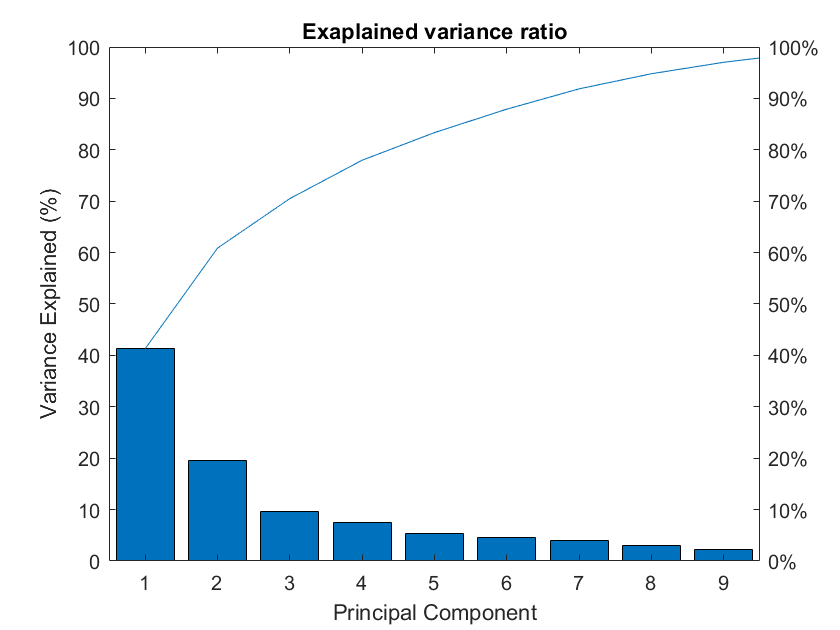

pareto(explained) 
xlabel('Principal Component')
ylabel('Variance Explained (%)')
title('Exaplained variance ratio')

From the pareto chart, we can see that the first two principal components explained about 60% of variance, if we further include the thrid principal component, we will be able to explain 70% of variance. Knowing how much of variance is explained by principal components is important when we're doing dimensionality reduction, it is a indication of validity of the PCA.

## Question 4 - Score Plot

Perform dimensionality reduction to the data, and visualise the data on a score plot using the first two principal components. Use different color to distinguish champions with different type. Judging by the champions' types, how well does PCA explain the given dataset?

### Answer 4

To plot the data in each type with different color, we can draw them seperately. First use hold on to keep drawing in the same figure, then for each type, search for the indices of the data with the same type, and draw them together. Since we draw each type of data seperately, MATLAB will automatically assign different color for each type.

types = unique(T{:,'Type'}) % get all uniques types

types = 6×1 cell array
    {'Assassins'}
    {'Fighters' }
    {'Mages'    }
    {'Marksmen' }
    {'Support'  }
    {'Tanks'    }


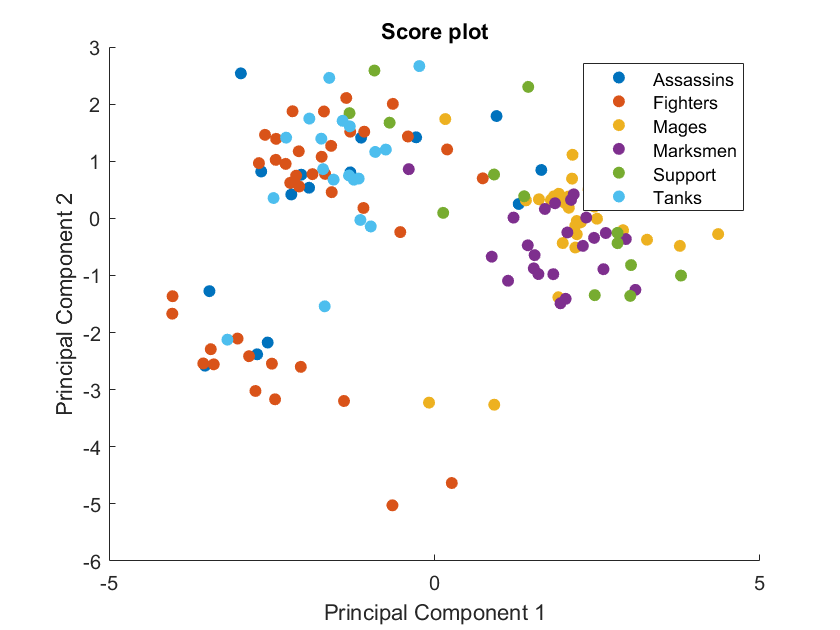

figure
hold on
for i = 1:length(types) % for each type
	type = types(i);
	indices = string(T{:,"Type"}) == type; % find the indices of rows with the type
	scatter(scores(indices,1), scores(indices,2), 'filled') % plot the data points with the type
end
legend(types)
xlabel('Principal Component 1')
ylabel('Principal Component 2')
title('Score plot')
hold off

We can roughly see that the champions with the same type "group together" in the score plot. This means that the 2D basis found by PCA successfully distinguish the features of the champions. 

## Insight from this PCA analysis

### For those who don't play League of Legends (or have little knowlegue about this game)

PCA is able to help you quickly get some useful information about this game from the given dataset.  

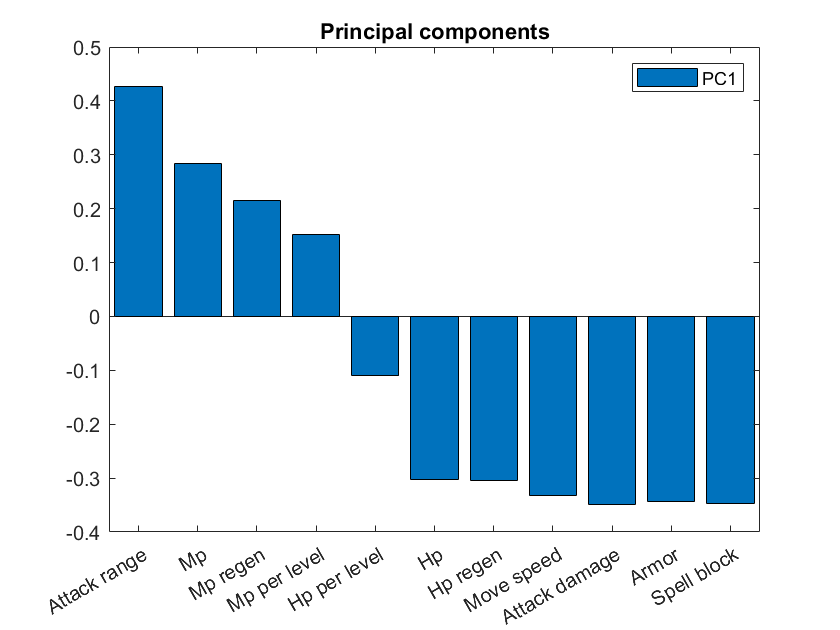

From the composition of prinicpal components, we can see that the first principal component indicates champions with long attack range, but with little health and armor, if you already know this game, this typically represents rangers champions like Mage or Marksman. On the contrary, if a champion with short attach range but has high health and armor, its score on the first principal component must be low (or negative), and this typically indicates melee champions like Fighters or Tanks. 

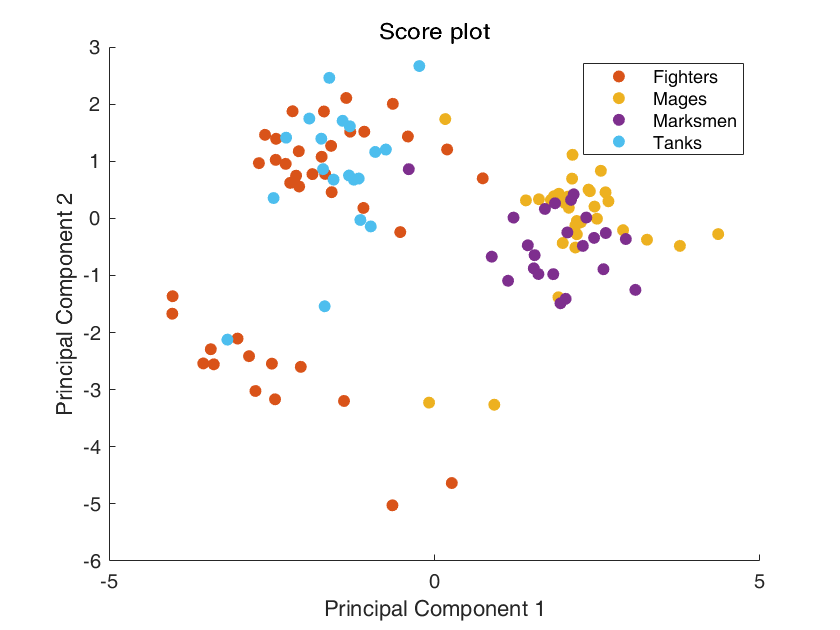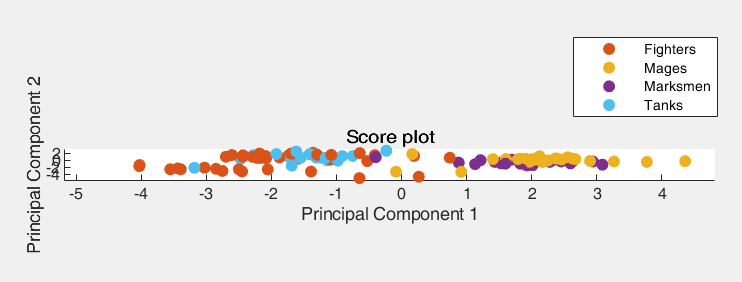

We can observe this from the score plot, clearly most of rangers are on the right hand side of the plot, whereas most of the melee are on the left hand side. The first principal component also reflects the largest variance among the dataset, this implies that the game makers tend to differentiate rangers and melee the most. This is an interesting insight as we can reveal the design principle of the game makers by this analysis.

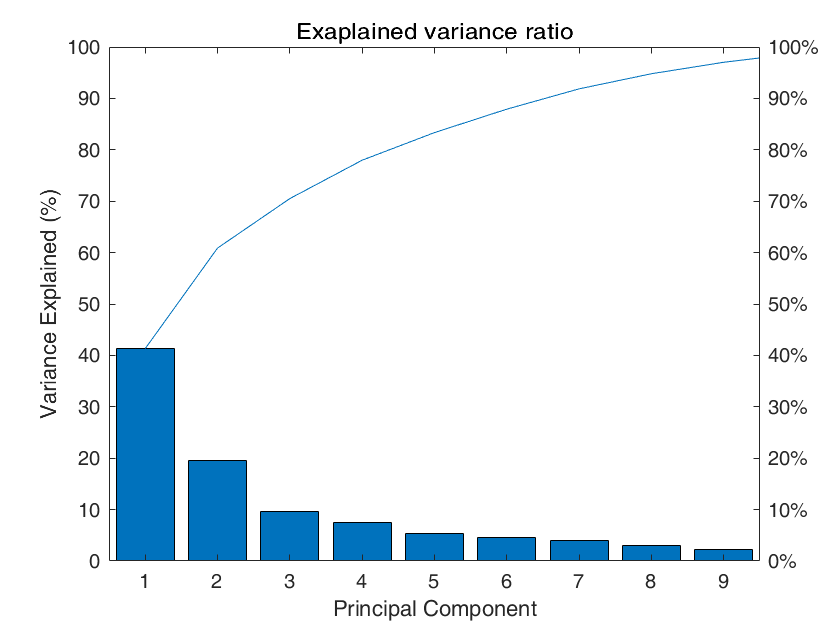

From the explained variance ratio, we see that the first principal component explained only about 40% of the variance. This is reasonable as it only distinguish rangers and melee, but it's still incredible as we've only take the first principal component into account, and originally there are a total of 11 variables. With the same method described above, if we take more principal components into consideration, we'll see more types of champions can be explained.

### For those who are already familiar with this game

After reading through the previous paragraph, you might say "Yeah, I've already know that. There's nothing I can learn from it." Bare in mind that in real world scenarios, you probably won't have any knowledge about the data you're going to analysis beforehand. In this case, PCA serves as a quick and easy method to help you reducing the complexity of the data as well as analysing the data systematically. 

Apart from that, there's actually more things worth you dig deeper. 

For example, it's obvious that there are actually two groups of Fighters showing in the score plot: one group in the quadrant II and the other one in the quadrant III. Would you be able to explain why? Can we classify them by introducing a new type from Fighters? Can you characterise the champions between these two groups of Fighters?

Furthermore, we can see that there are some champions locate far away from it's group (e.g. the two Mages with $\textrm{PC1}\approx 0$). Why are those champions different from the others? What kind of unique feature they have? Would that feature be an advantage or disadvantage?

I leave these questions for you to discover by yourself.